# 3.2 ARMA(p,q) with q=0

Alexandre Rey, MSE, MA-StatDig, 03.2022

clear;
rng('default');
rand(1);    % keep it to get same results as teacher

addpath('../functions/');

## Autoregressive random process (CompEx 3.4)

Let's consider the autoregressive AR(2) random process given by the difference equation:


$$x(n) = a(1)x(n-1)+a(2)x(n-2)+b(0)v(n)$$


With $v(n)$ a unit variance white noise.

### Generate v(n)

With $a(1)=0$, $a(2)=-0.81$ and $b(0)=1$, generate a 24-samples of the random process $x(n)$. Generate $v(n)$ with the function `randn()`, as the gaussian white noise.

N = 24;
n = 0:N-1;

vn = randn(1, N);
b = 1

b = 1

a = [1, 0, -0.81]

a =     1.0000         0   -0.8100


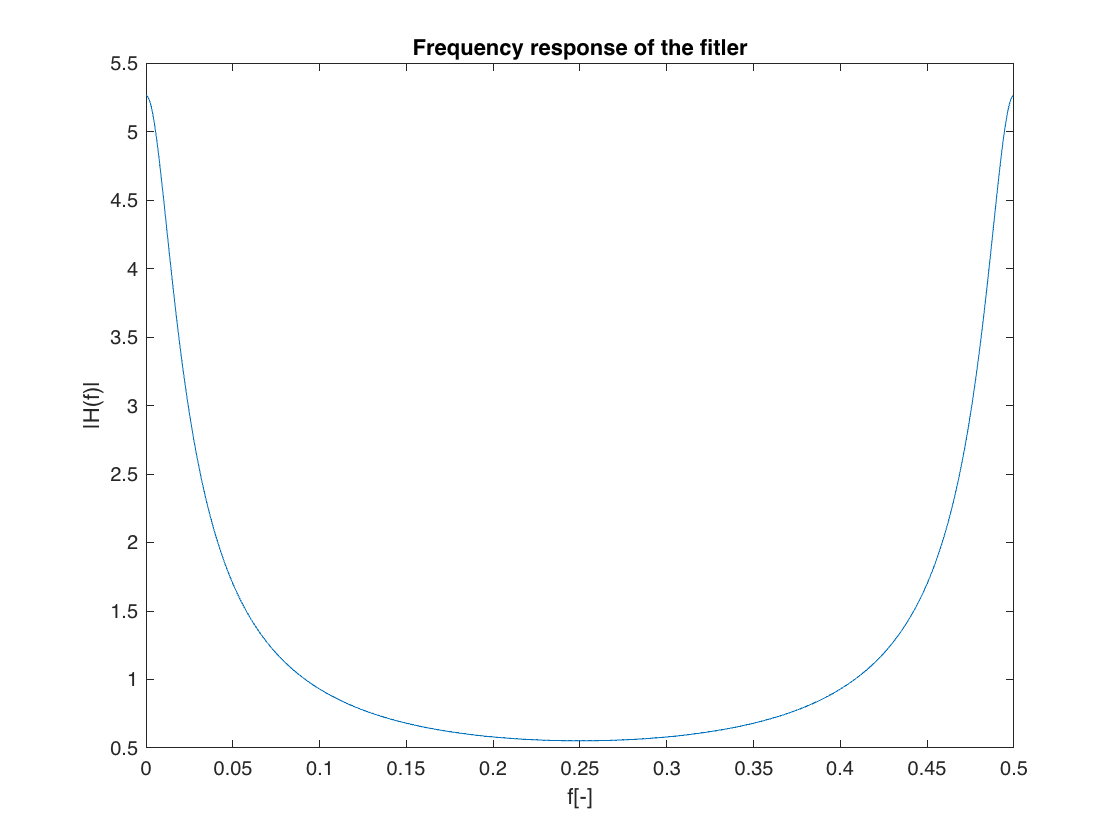

[H, W] = freqz(b, a, 1000);
figure;
    plot(W/(2*pi), abs(H));
    title('Frequency response of the fitler');
    xlabel('f[-]');
    ylabel('|H(f)|');

Compute $x(n)$ with the `filter` function.

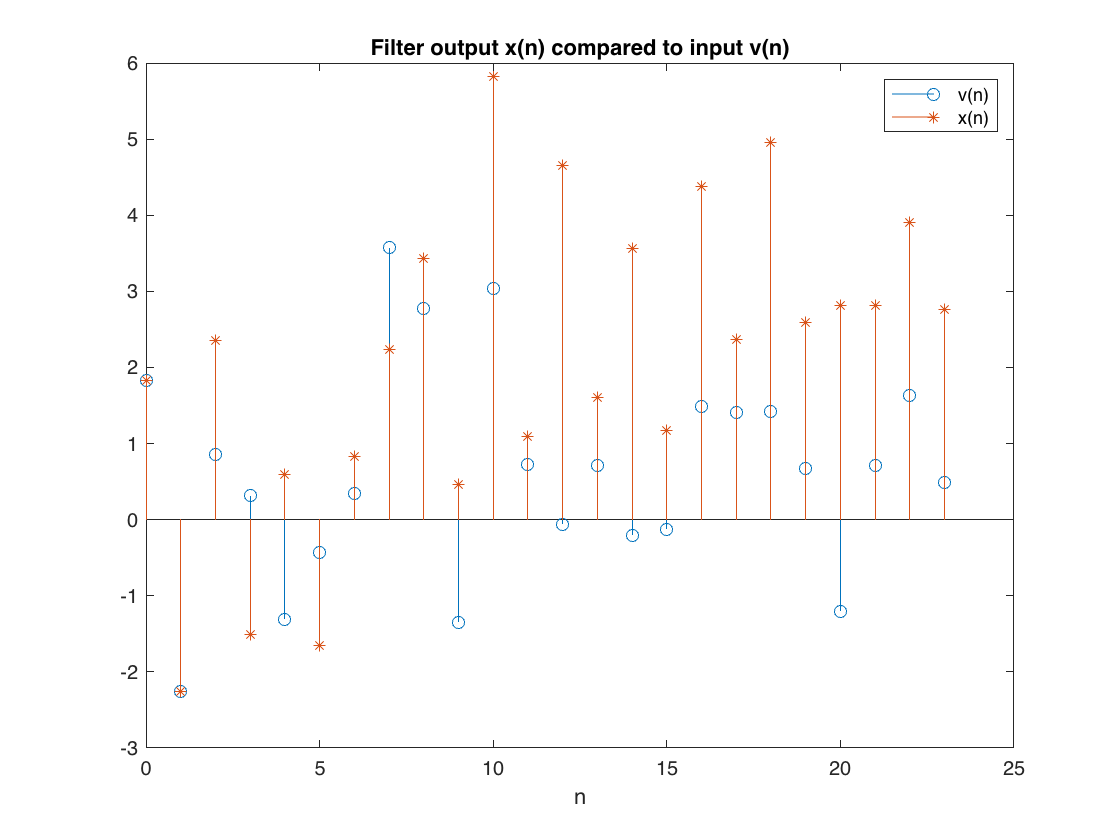

xn = filter(b, a, vn);   % vn as input
figure;
    stem(n, vn);
    hold on;
    stem(n, xn, '*');
    hold off;
    title('Filter output x(n) compared to input v(n)');
    xlabel('n');
    legend('v(n)', 'x(n)');

## 2. Autocorrelation

Estimate the autocorrelation sequence of $x(n)$ using the sample autocorrelation:

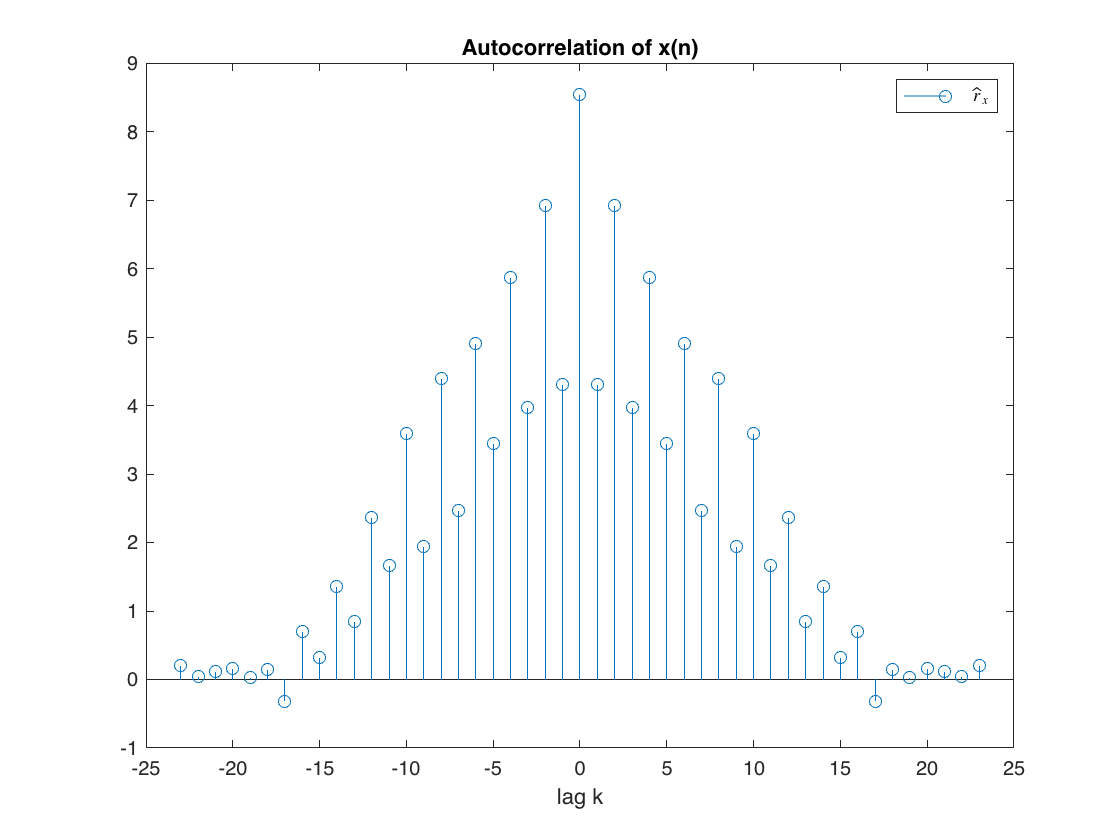

[rxhat, k] = mySampleAutocorr(xn, 'biased');

figure;
    stem(k, rxhat);
    title('Autocorrelation of x(n)')
    legend('$\hat{r}_x$', 'Interpreter', 'latex');
    xlabel('lag k');

## 3. Power spectrum

Estimate the power spectrum from the sample autocorrelation:

NFFT = 48;
w = -pi : 2*pi/NFFT : pi-2*pi/NFFT;
rxhat_p = [zeros(1,NFFT/2 - N+1), rxhat, zeros(1, NFFT/2 - N)]; % 0-padding
Pxfft = fftshift(fft(fftshift(rxhat_p), NFFT));

Pxfft_real = real(Pxfft);

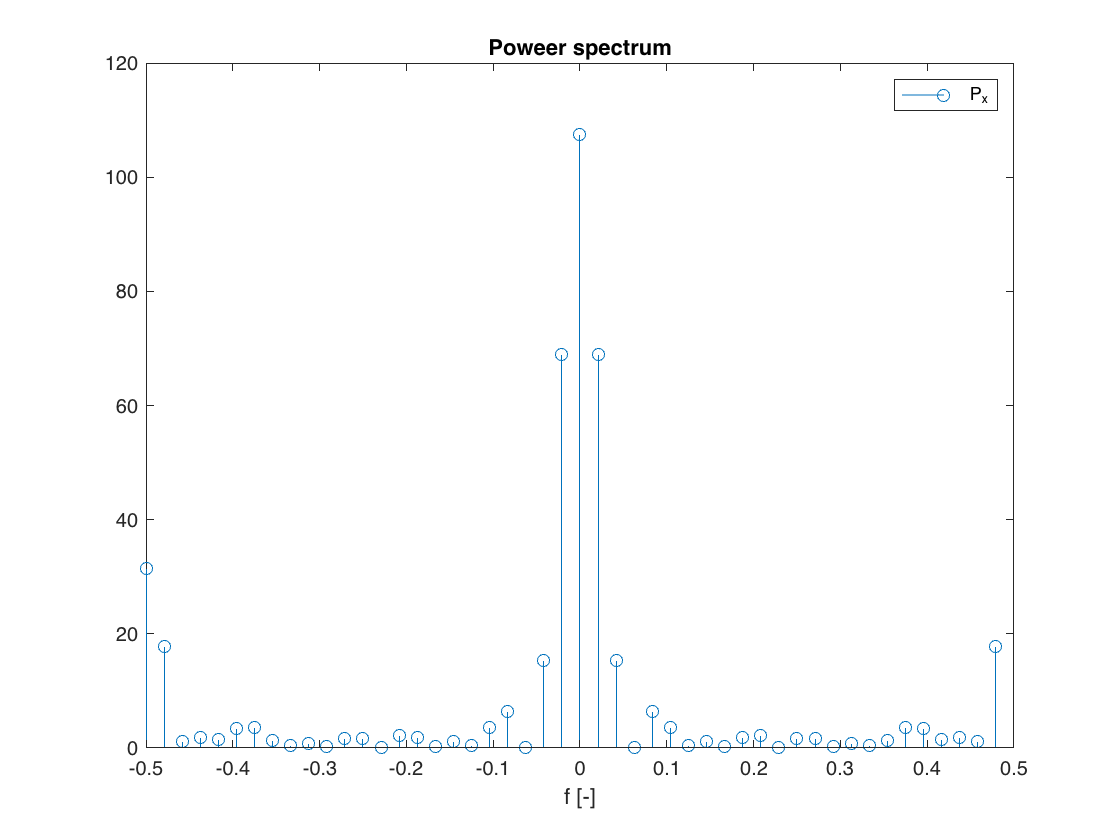

figure;
    stem(w/(2*pi), Pxfft_real)
    title('Poweer spectrum')
    xlabel('f [-]')
    legend('P_x')

## 4. Yule-Walker

From the estimation of the autocorrelation $\hat{r}_x(k)$ use the Youle Walker equation to find the values of the coefficients $a(1)$ and $a(2)$ and $b(0)$ and comment the accuracy of the estimation:

$\left[ \matrix{r_x(0) & r_x(-1) & r_x(-2) \cr r_x(1) & r_x(0) & r_x(-1) \cr r_x(2) & r_x(1) & r_x(0)} \right] \left[ \matrix{1\cr a(1)\cr a(2)}\right] = \sigma_v |b(0)|^2 \left[ \matrix{1\cr 0\cr 0}\right] $     (2)

In this case the process is real value and stationary so $r_x(-1) = r_x(1)$.

Take the values computed for rxhat for $k = 0,1,2$ and $\sigma_v^2=1$

% Rx = [rxhaat(N) rxhat(N-1) rxhat(N-2); ...]
Rxx = [rxhat(k==0) rxhat(k==-1) rxhat(k==2);
      rxhat(k==1) rxhat(k==0)  rxhat(k==-1);
      rxhat(k==2) rxhat(k==1)  rxhat(k==0)]

Rxx =     8.5457    4.3075    6.9229
    4.3075    8.5457    4.3075
    6.9229    4.3075    8.5457


sigma_v = 1;

% inv(Rxx(2:3, 2:3)) * [-rxhat(k==1); -rxhat(k==2)]
A = Rxx(2:3, 2:3) \ [-rxhat(k==1); -rxhat(k==2)] % A = [a(1); a(2)]

A =    -0.1283
   -0.7454


% En développant algébriquement (3 équations à 3 inconnues)
a2 = (rxhat(N+1)^2/rxhat(N) - rxhat(N+2)) / (rxhat(N) - rxhat(N+1)^2/rxhat(N))

a2 = -0.7454

a1 = -rxhat(N+1)/rxhat(N) - rxhat(N+1)/rxhat(N) * a2

a1 = -0.1283

b0_sq = rxhat(N) + a1*rxhat(k==-1) + a2*rxhat(k==-2) % b0^2

b0_sq = 2.8324

b0 = sqrt(b0_sq)

b0 = 1.6830